% Problem 1 Exam 12-01-2023
% Jim Brouzoulis
clc, clear variables, close all 

% Input data
A = 10;  % [m^2]
k_al = 240;   % thermal conductivity [J/C m s]
k_new = 0.02;
r_in = 40e-3;  
h_al = 2e-3;  % al thickness
h_new = 4e-3; % insulation thickness
r_out = r_in + 2*h_al + h_new; 
 
alpha = 6 % W/m^2*K

alpha = 6

T_in = 50; % inner wall temperature
T_out = 20; % outer ambient temperature 

k = [k_al k_new k_al];

Edof = [1  1 2
        2  2 3
        3  3 4];
coords = [r_in, r_in + h_al, r_in + h_al + h_new, r_out] 

coords =     0.0400    0.0420    0.0460    0.0480



ndofs = 4;
nel = 3

nel = 3

K = zeros(ndofs, ndofs);
f = zeros(ndofs, 1);
for el = 1:nel
    r_i = coords(el);
    r_j = coords(el+1);
    Le = r_j - r_i;
    Ke = k(el)*(r_j + r_i)/(2*Le) * [ 1 -1
                                     -1  1]; 
    K = assem(Edof(el, :), K, Ke);
end
K

K = 1.0e+03 *

    4.9200   -4.9200         0         0
   -4.9200    4.9202   -0.0002         0
         0   -0.0002    5.6402   -5.6400
         0         0   -5.6400    5.6400



bc = [1 T_in]; % temperature at the inner wall
% add convection contributions corresponding to the right end
K(end, end) = K(end, end) + alpha * r_out;
f(end) = f(end) + alpha*T_out * r_out;
a = solveq(K, f, bc)

a =    50.0000
   49.9992
   32.9922
   32.9915



q_out = alpha*(a(end) - T_out)

q_out = 77.9491

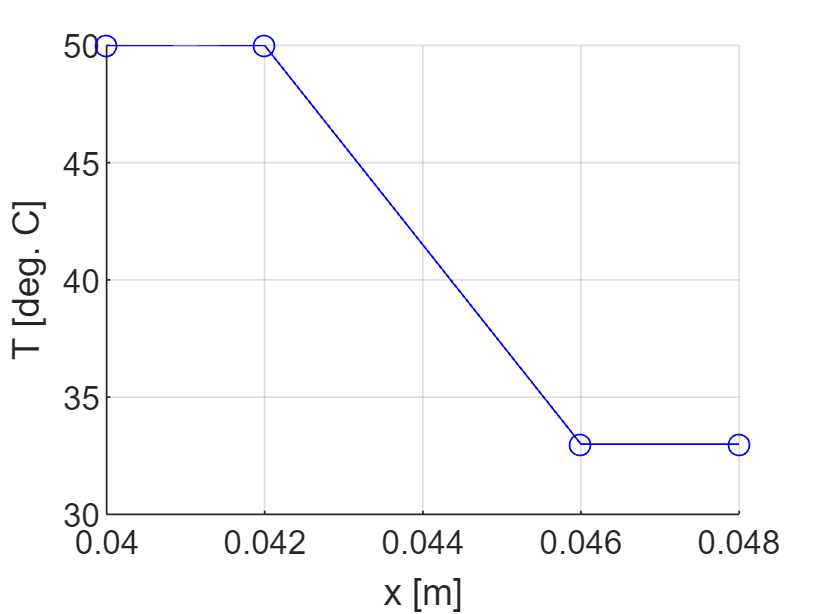

figure()
hold on
grid on
plot(coords, a, 'bo-')
xlabel('x [m]')
ylabel('T [deg. C]')